clear;
clc;

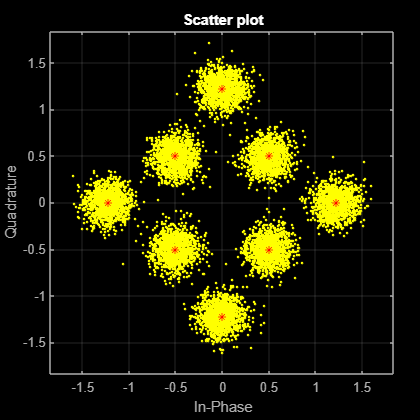

%% Building the constellation for QPSK
c = [0.5+0.5*1i, 0.5-0.5*1i, -0.5+0.5*1i, -0.5-0.5*1i...
    sqrt(3/2), -sqrt(3/2), sqrt(3/2)*1i, -sqrt(3/2)*1i];
sigpower = pow2db(mean(abs(c).^2));
M = length(c);

x = randi([0 M-1],10^4,1);
mod_x = genqammod(x,c);

y = awgn(mod_x,15,sigpower);

h = scatterplot(y);
hold on
scatterplot(c,[],[],'r*',h)
grid
hold off

close
c_4design = [-sqrt(1.1), sqrt(0.9)*1i, -sqrt(0.9)*1i, sqrt(1.1)];
M4_sigpower = pow2db(mean(abs(c_4design).^2));
M = length(c_4design);

M4_x = randi([0 M-1],10^8,1);
M4_mod_x = genqammod(M4_x,c_4design);

y = awgn(M4_mod_x,15,M4_sigpower);

h = scatterplot(y);
hold on
scatterplot(c_4design,[],[],'r*',h)
grid
hold off

close
SNR = 0:3:15;
d_min = sqrt(2);
Bit_energy = 0.5;
sigma = sqrt(Bit_energy./(10.^(SNR./10)));
theory_ub = (M-1)*qfunc(d_min./(2*sigma));

M4_error_rate = zeros(size(SNR));
for i = 1:length(SNR)
    M4_noisy_sig = awgn(M4_mod_x,SNR(i),M4_sigpower);
    M4_detected = genqamdemod(M4_noisy_sig,c_4design);
    [M4_numErrors,M4_ser] = symerr(M4_x,M4_detected);
    M4_error_rate(i) = M4_ser;
end

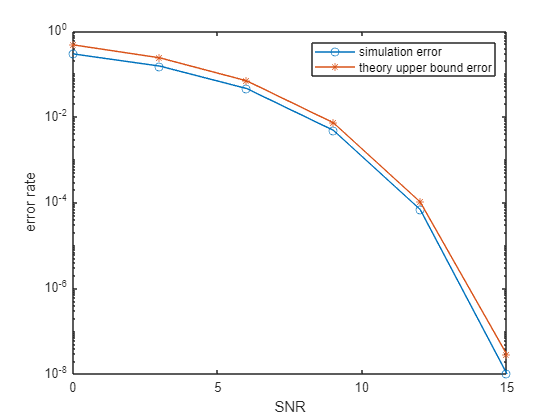

close
semilogy(SNR, M4_error_rate,'-o')
hold on
semilogy(SNR, theory_ub,'-*')
xlabel('SNR')
ylabel('error rate')
legend("simulation error", "theory upper bound error")

close
c_8QAM = [0.5+0.5*1i, 0.5-0.5*1i, -0.5+0.5*1i, -0.5-0.5*1i...
    sqrt(3/2), -sqrt(3/2), sqrt(3/2)*1i, -sqrt(3/2)*1i];
QAM_sigpower = pow2db(mean(abs(c_8QAM).^2));
M = length(c_8QAM);

x_8QAM = randi([0 M-1],10^8,1);
mod_x_8QAM = genqammod(x_8QAM,c_8QAM);

d_min = sqrt((sqrt(3/2)-0.5)^2+0.5^2);
Bit_energy = 1/3;
sigma = sqrt(Bit_energy./(10.^(SNR./10)));
theory_ub_8QAM = (M-1)*qfunc(d_min./(2*sigma));

QAM_error_rate = zeros(size(SNR));
for i = 1:length(SNR)
    QAM_noisy_sig = awgn(mod_x_8QAM,SNR(i),QAM_sigpower);
    QAM_detected = genqamdemod(QAM_noisy_sig,c_8QAM);
    [QAM_numErrors,QAM_ser] = symerr(x_8QAM,QAM_detected);
    QAM_error_rate(i) = QAM_ser;
end

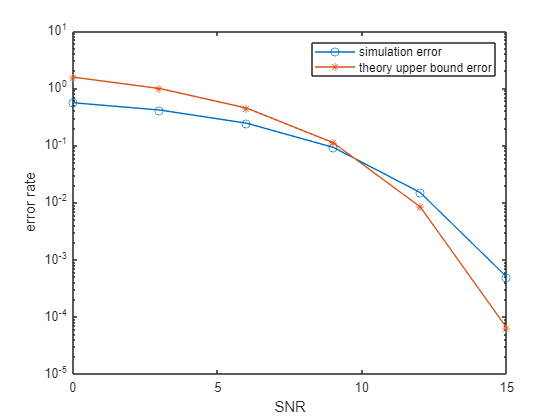

semilogy(SNR, QAM_error_rate,'-o')
hold on
semilogy(SNR, theory_ub_8QAM,'-*')
xlabel('SNR')
ylabel('error rate')
legend("simulation error", "theory upper bound error")